clear; clc; close all;

%% =================================================================
%% 1. CAMERA PERCEPTION & SETUP
%% =================================================================
disp('Initializing RealSense Camera...');

Initializing RealSense Camera...


% Initialize pipeline and config
pipe = realsense.pipeline();
cfg = realsense.config();

% Enable streams (Color and Depth)
cfg.enable_stream(realsense.stream.depth, 640, 480, realsense.format.z16, 30);
cfg.enable_stream(realsense.stream.color, 640, 480, realsense.format.rgb8, 30);

% Initialize pointcloud object and alignment
pc = realsense.pointcloud();
align_to_color = realsense.align(realsense.stream.color);

% Start pipeline
profile = pipe.start(cfg);

disp('Warming up camera and capturing frame...');

Warming up camera and capturing frame...


for i = 1:10 % Let auto-exposure settle
    fs = pipe.wait_for_frames();
    fs = align_to_color.process(fs);
    depth_frame = fs.get_depth_frame();
    color_frame = fs.get_color_frame();
    
    pc.map_to(color_frame);
    points = pc.calculate(depth_frame);
    vtx = points.get_vertices(); % Vertices are in METERS
end

% Stop streaming once we have a solid frame
pipe.stop();
disp('Frame captured. Camera stopped.');

Frame captured. Camera stopped.



% Extract RGB Image
color_data = color_frame.get_data();
I = permute(reshape(color_data', [3, 640, 480]), [3 2 1]);

%% =================================================================
%% 2. WORLD TRANSLATION & IMAGE MAPPING SETUP
%% =================================================================
% Your provided Transformation Matrix (Camera to World)
T_world_camera =  [-0.0105   -0.9991   -0.0408    0.0065;
                   -0.9999    0.0103    0.0047    0.0586;
                   -0.0043    0.0408   -0.9992    0.7110;
                         0         0         0    1.0000];

% Masking setup to map 2D pixels to 3D depth vertices
valid_depth = (vtx(:,3) > 0); 
[U, V] = meshgrid(1:640, 1:480); % U is X (columns), V is Y (rows)
U_1d = reshape(U', [], 1);
V_1d = reshape(V', [], 1);

%% =================================================================
%% 3. ARUCO DETECTION & POSE ESTIMATION
%% =================================================================
disp('Detecting ArUco Markers...');

Detecting ArUco Markers...



% Detect markers using default dictionary
[markerIds, markerLocs] = readArucoMarker(I);

if isempty(markerIds)
    disp('No ArUco markers detected in the scene.');
    imshow(I); title('No Markers Detected');
    return;
end

results = []; % To store data for reporting

for i = 1:length(markerIds)
    current_id = markerIds(i);
    corners = markerLocs(:,:,i); % 4x2 matrix of [x, y] coordinates
    
    % Create a 2D binary mask from the 4 ArUco corners
    mask_2d = poly2mask(corners(:,1), corners(:,2), 480, 640);
    mask_1d = reshape(mask_2d', [], 1);
    
    % Extract valid 3D points belonging ONLY to this specific marker
    valid_mask = valid_depth & mask_1d;
    obj_vtx = vtx(valid_mask, :);
    
    if isempty(obj_vtx)
        fprintf('WARNING: Marker %d found in RGB, but 3D depth data is missing.\n', current_id);
        continue;
    end
    
    % --- CALCULATE POSITION ---
    % Find centroid in camera frame
    pos_cam = mean(obj_vtx, 1);
    
    % Convert to homogeneous coordinates and transform to World Frame
    pos_world_homog = T_world_camera * [pos_cam, 1]';
    curr_pos_world = pos_world_homog(1:3)'; 
    
    % --- CALCULATE ORIENTATION (ANGLE) ---
    % ArUco marker corners are ALWAYS returned in a specific order:
    % 1: Top-Left, 2: Top-Right, 3: Bottom-Right, 4: Bottom-Left
    
    % Calculate the 2D vector of the marker's "Top Edge" (Corner 1 to Corner 2)
    dx_cam = corners(2, 1) - corners(1, 1);
    dy_cam = corners(2, 2) - corners(1, 2);
    
    % Extract just the 3x3 Rotation matrix from your T_world_camera
    R_world_camera = T_world_camera(1:3, 1:3);
    
    % Project this 2D vector into 3D camera space (assuming it lays flat, dz=0)
    vec_cam = [dx_cam; dy_cam; 0];
    
    % Transform the vector from camera rotation to world rotation
    vec_world = R_world_camera * vec_cam;
    
    % Compute the final yaw angle in the World Frame (using X and Y)
    curr_angle_deg = rad2deg(atan2(vec_world(2), vec_world(1)));
    
    % Store for reporting
    results(i).id = current_id;
    results(i).world_X = curr_pos_world(1) * 1000; % Convert to mm
    results(i).world_Y = curr_pos_world(2) * 1000; % Convert to mm
    results(i).world_Z = curr_pos_world(3) * 1000; % Convert to mm
    results(i).angle = curr_angle_deg;
    results(i).pixel_x = mean(corners(:,1)); % For plotting
    results(i).pixel_y = mean(corners(:,2)); % For plotting
end

%% =================================================================
%% 4. RESULTS OUTPUT & VISUALIZATION
%% =================================================================
% Print Table to Console
fprintf('\n==========================================================\n');

fprintf(' ARUCO MARKER WORLD POSE REPORT \n');

 ARUCO MARKER WORLD POSE REPORT 


fprintf('==========================================================\n');

fprintf('%-10s | %-8s | %-8s | %-8s | %-8s\n', ...
    'Marker ID', 'World X', 'World Y', 'World Z', 'Angle');

Marker ID  | World X  | World Y  | World Z  | Angle   


fprintf('----------------------------------------------------------\n');

----------------------------------------------------------



for i = 1:length(results)
    if isempty(results(i).id), continue; end
    fprintf('%-10d | %-8.1f | %-8.1f | %-8.1f | %-8.1f°\n', ...
        results(i).id, results(i).world_X, results(i).world_Y, results(i).world_Z, results(i).angle);
end

2          | -162.2   | -159.4   | 20.4     | -47.5   °
0          | 138.9    | -10.3    | 7.4      | -1.9    °


fprintf('==========================================================\n\n');

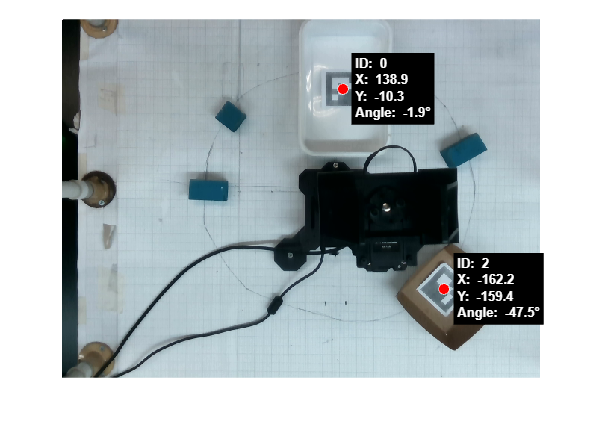


% Display Visual Map
figure('Name', 'ArUco World Pose', 'NumberTitle', 'off', 'Position', [100, 100, 800, 600]);
imshow(I); 
hold on;

for i = 1:length(results)
    if isempty(results(i).id), continue; end
    r = results(i);
    
    % Plot the centroid
    plot(r.pixel_x, r.pixel_y, 'o', 'MarkerSize', 8, 'MarkerEdgeColor', 'w', 'MarkerFaceColor', 'r');
    
    % Annotate with World Coordinates and Angle
    annot_str = sprintf('ID: %d\nX: %.1f\nY: %.1f\nAngle: %.1f\\circ', ...
                        r.id, r.world_X, r.world_Y, r.angle);
    
    text(r.pixel_x + 15, r.pixel_y, annot_str, ...
        'Color', 'w', ...
        'BackgroundColor', 'k', ...
        'FontSize', 10, ...
        'FontWeight', 'bold', ...
        'Margin', 2);
end
hold off;

clear; clc; close all;

%% =================================================================
%% 1. CAMERA PERCEPTION & SETUP
%% =================================================================
% Initialize pipeline and config
pipe = realsense.pipeline();
cfg = realsense.config();

% Enable streams
cfg.enable_stream(realsense.stream.depth, 640, 480, realsense.format.z16, 30);
cfg.enable_stream(realsense.stream.color, 640, 480, realsense.format.rgb8, 30);

% Initialize pointcloud object
pc = realsense.pointcloud();
align_to_color = realsense.align(realsense.stream.color);

% Start pipeline
profile = pipe.start(cfg);

disp('Warming up camera...');

Warming up camera...


for i = 1:10
    fs = pipe.wait_for_frames();
    fs = align_to_color.process(fs);
    depth_frame = fs.get_depth_frame();
    color_frame = fs.get_color_frame();
    
    pc.map_to(color_frame);
    points = pc.calculate(depth_frame);
    vtx = points.get_vertices(); % Note: Vertices are in METERS
end

% Stop streaming
pipe.stop();
disp('Camera stopped. Processing final frame for Scene Analysis...');

Camera stopped. Processing final frame for Scene Analysis...



% Extract RGB & HSV
color_data = color_frame.get_data();
I = permute(reshape(color_data', [3, 640, 480]), [3 2 1]);
hsvI = rgb2hsv(I);
H = hsvI(:,:,1); S = hsvI(:,:,2); V = hsvI(:,:,3);

% Transformation Matrix (Camera to World)
T_world_camera =  [-0.0105   -0.9991   -0.0408    0.0065;
                   -0.9999    0.0103    0.0047    0.0586;
                   -0.0043    0.0408   -0.9992    0.7110;
                         0         0         0    1.0000];

valid_depth = (vtx(:,3) > 0); 

%% =================================================================
%% 2. DETECT DESTINATION TRAY (VIA ARUCO MARKER)
%% =================================================================
disp('Detecting ArUco Marker for Destination Tray...');

Detecting ArUco Marker for Destination Tray...


[markerIds, markerLocs] = readArucoMarker(I);

bin_found = false;
if ~isempty(markerIds)
    % Use the first detected marker as the destination
    corners = markerLocs(:,:,1);
    
    % Create a 2D binary mask from the ArUco corners
    mask_2d = poly2mask(corners(:,1), corners(:,2), 480, 640);
    mask_1d = reshape(mask_2d', [], 1);
    
    bin_vtx = vtx(valid_depth & mask_1d, :);
    
    if ~isempty(bin_vtx)
        bin_pos_cam = mean(bin_vtx, 1);
        bin_pos_world_homog = T_world_camera * [bin_pos_cam, 1]';
        
        % Convert to millimeters for robot IK!
        blue_place_x = bin_pos_world_homog(1) * 1000;
        blue_place_y = bin_pos_world_homog(2) * 1000;
        bin_found = true;
        
        % Save 2D coords for drawing later
        bin_pixel_x = mean(corners(:,1));
        bin_pixel_y = mean(corners(:,2));
        
        fprintf('ArUco Tray Detected at World X: %.1f mm, Y: %.1f mm\n', blue_place_x, blue_place_y);
    end
end

ArUco Tray Detected at World X: -193.2 mm, Y: -13.3 mm



if ~bin_found
    disp('WARNING: ArUco Tray not found. Defaulting to x=160, y=0');
    blue_place_x = 160; blue_place_y = 0;
end

%% =================================================================
%% 3. EXTRACT TARGETS (BLUE & GREEN BLOCKS)
%% =================================================================
% Blue Mask
hueMask_B = (H > 0.52) & (H < 0.65); 
level_B = max(graythresh(S), 0.40); 
mask_blue = bwareaopen(imfill(hueMask_B & (S > level_B) & (V > 0.25), 'holes'), 100);

% Green Mask
H_MIN_GREEN = 0.232; H_MAX_GREEN = 0.490;
S_MIN_GREEN = 0.292; S_MAX_GREEN = 1.000;
V_MIN_GREEN = 0.138; V_MAX_GREEN = 0.579;
mask_green = bwareaopen(imfill((H >= H_MIN_GREEN) & (H <= H_MAX_GREEN) & ...
            (S >= S_MIN_GREEN) & (S <= S_MAX_GREEN) & ...
            (V >= V_MIN_GREEN) & (V <= V_MAX_GREEN), 'holes'), 100);

jaw_tolerance_deg = 13;

% Create 2D Pixel maps to track cluster centroids on the image
[U, V] = meshgrid(1:640, 1:480); % U is X (columns), V is Y (rows)
U_1d = reshape(U', [], 1);
V_1d = reshape(V', [], 1);

% Helper function to process point clouds into target arrays
function targets = get_targets(mask, vtx, valid_depth, T_world_camera, jaw_tolerance_deg, color_name, U_1d, V_1d)
    targets = []; target_idx = 0;
    mask_1d = reshape(mask', [], 1);
    
    valid_mask = valid_depth & mask_1d;
    obj_vtx = vtx(valid_mask, :);
    
    % Extract the corresponding 2D pixel coordinates for these valid points
    obj_u = U_1d(valid_mask);
    obj_v = V_1d(valid_mask);
    
    if isempty(obj_vtx), return; end
    
    ptCloud = pointCloud(obj_vtx);
    [labels, numClusters] = pcsegdist(ptCloud, 0.008);
    
    for c = 1:numClusters
        cubeIndices = find(labels == c);
        if length(cubeIndices) < 150, continue; end
        
        cubeCloud = select(ptCloud, cubeIndices);
        
        % Calculate 2D Centroid for the image annotation
        pixel_x = mean(obj_u(cubeIndices));
        pixel_y = mean(obj_v(cubeIndices));
        
        % Centroid Math
        pos_cam = mean(cubeCloud.Location, 1);
        pos_world_homog = T_world_camera * [pos_cam, 1]';
        curr_pos_world = pos_world_homog(1:3)';
        
        % =========================================================
        % REPLACEMENT: Orientation Math (Minimum Bounding Box)
        % =========================================================
        points_cam_homog = [cubeCloud.Location, ones(size(cubeCloud.Location, 1), 1)]'; 
        points_world = (T_world_camera * points_cam_homog)'; 
        
        max_z = max(points_world(:, 3)); 
        top_face_indices = points_world(:, 3) > (max_z - 0.005);
        top_points_xy = points_world(top_face_indices, 1:2); 
        
        % 1. Sweep angles from 0 to 89 to find the tightest bounding box
        search_angles = 0:1:89;
        areas = zeros(size(search_angles));
        box_widths = zeros(size(search_angles));
        box_heights = zeros(size(search_angles));
        
        for a_idx = 1:length(search_angles)
            t = deg2rad(search_angles(a_idx));
            % Unit vectors along and perpendicular to the search angle
            u = [cos(t); sin(t)];
            v = [-sin(t); cos(t)];
            
            % Project points onto the vectors
            proj_u = top_points_xy * u;
            proj_v = top_points_xy * v;
            
            % Calculate width and height of the box at this rotation
            w = max(proj_u) - min(proj_u);
            h = max(proj_v) - min(proj_v);
            
            areas(a_idx) = w * h;
            box_widths(a_idx) = w;
            box_heights(a_idx) = h;
        end
        
        % 2. Get the angle that minimizes the bounding box area
        [~, min_idx] = min(areas);
        best_angle_deg = search_angles(min_idx);
        final_w = box_widths(min_idx);
        final_h = box_heights(min_idx);
        
        % 3. Determine shape & exact angle
        aspect_ratio = max(final_w, final_h) / min(final_w, final_h);
        is_rect = false;
        curr_angle_deg = best_angle_deg;
        
        if aspect_ratio > 1.3 
            is_rect = true;
            % For rectangles, we must align with the longer side
            if final_h > final_w
                curr_angle_deg = mod(best_angle_deg + 90, 180);
            end
        end
        
        % =========================================================
        % REPLACEMENT: Feasibility Math (Cleaned up wrapping)
        % =========================================================
        theta_arm_deg = rad2deg(atan2(curr_pos_world(2), curr_pos_world(1)));
        
        % Calculate relative angular difference
        % Since parallel jaws open symmetrically, grabbing an object aligned at 
        % 0 degrees or 90 degrees relative to the arm approach is identical.
        angular_diff = curr_angle_deg - theta_arm_deg;
        
        % Wrap cleanly to [-45, 45] to find the true shortest rotational error
        curr_angular_error = abs(mod(angular_diff + 45, 90) - 45);
        
        target_idx = target_idx + 1;
        targets(target_idx).id = target_idx;
        targets(target_idx).color = color_name;
        targets(target_idx).pos = curr_pos_world;
        targets(target_idx).angle = curr_angle_deg;
        targets(target_idx).error = curr_angular_error;
        targets(target_idx).feasible = (curr_angular_error <= jaw_tolerance_deg);
        targets(target_idx).is_rect = is_rect;
        
        % Store 2D coordinates
        targets(target_idx).pixel_x = pixel_x;
        targets(target_idx).pixel_y = pixel_y;
    end
end

% Call the function for both colors
blue_targets = get_targets(mask_blue, vtx, valid_depth, T_world_camera, jaw_tolerance_deg, 'Blue', U_1d, V_1d);
green_targets = get_targets(mask_green, vtx, valid_depth, T_world_camera, jaw_tolerance_deg, 'Green', U_1d, V_1d);

% To maintain sequential IDs overall:
all_targets = [];
current_id = 1;
for i = 1:length(blue_targets)
    blue_targets(i).id = current_id; current_id = current_id + 1;
end
for i = 1:length(green_targets)
    green_targets(i).id = current_id; current_id = current_id + 1;
end
all_targets = [blue_targets, green_targets];

%% =================================================================
%% 4. DEBUGGING / VERIFICATION TABLE
%% =================================================================
fprintf('\n===========================================================================\n');

fprintf(' DETECTED OBJECTS REPORT \n');

 DETECTED OBJECTS REPORT 


fprintf('===========================================================================\n');

fprintf('%-5s | %-7s | %-6s | %-6s | %-6s | %-7s | %-6s | %-10s\n', ...
    'ID', 'Color', 'X(mm)', 'Y(mm)', 'Z(mm)', 'Angle', 'IsRect', 'Feasible');

ID    | Color   | X(mm)  | Y(mm)  | Z(mm)  | Angle   | IsRect | Feasible  


fprintf('---------------------------------------------------------------------------\n');

---------------------------------------------------------------------------



for i = 1:length(all_targets)
    t = all_targets(i);
    feasible_str = 'YES'; if ~t.feasible, feasible_str = 'NO'; end
    rect_str = 'NO'; if t.is_rect, rect_str = 'YES'; end
    fprintf('%-5d | %-7s | %-6.1f | %-6.1f | %-6.1f | %-7.1f | %-6s | %-10s\n', ...
        t.id, t.color, t.pos(1)*1000, t.pos(2)*1000, t.pos(3)*1000, t.angle, rect_str, feasible_str);
end

1     | Blue    | 91.2   | -98.7  | 32.5   | 123.0   | YES    | YES       
2     | Blue    | 48.8   | 125.2  | 29.9   | 54.0    | NO     | NO        
3     | Blue    | -14.6  | 153.4  | 38.0   | 85.0    | YES    | YES       
4     | Green   | 130.5  | 0.0    | 21.9   | 89.0    | NO     | YES       
5     | Green   | 99.9   | 59.4   | 27.8   | 18.0    | YES    | YES       
6     | Green   | -95.8  | 169.4  | 41.2   | 107.0   | YES    | YES       
7     | Green   | -173.9 | -136.5 | 44.6   | 45.0    | YES    | YES       


fprintf('===========================================================================\n\n');


% Create the figure window explicitly
f = figure('Name', 'Workspace Target Debug', 'NumberTitle', 'off', 'Position', [100, 100, 800, 600]);
imshow(I); 
hold on;

% Draw ArUco Tray
if bin_found
    plot(bin_pixel_x, bin_pixel_y, 's', 'MarkerSize', 12, 'MarkerEdgeColor', 'w', 'MarkerFaceColor', 'y');
    text(bin_pixel_x + 20, bin_pixel_y, 'TRAY (ArUco)', 'Color', 'w', 'BackgroundColor', 'k', 'FontWeight', 'bold', 'FontSize', 10);
end

for i = 1:length(all_targets)
    t = all_targets(i);
    marker_color = 'b'; if strcmp(t.color, 'Green'), marker_color = 'g'; end
    text_bg = 'k'; if ~t.feasible, text_bg = 'r'; end
    
    plot(t.pixel_x, t.pixel_y, 'o', 'MarkerSize', 8, 'MarkerEdgeColor', 'w', 'MarkerFaceColor', marker_color);
    annot_str = sprintf('ID:%d | %d\\circ\nF:%d | R:%d', t.id, round(t.angle), t.feasible, t.is_rect);
    text(t.pixel_x + 15, t.pixel_y, annot_str, 'Color', 'w', 'BackgroundColor', text_bg, 'FontSize', 9, 'FontWeight', 'bold', 'Margin', 1);
end
hold off;

% UI Button
btn = uicontrol(f, 'Style', 'pushbutton', 'String', 'START ROBOT', 'Position', [20, 20, 150, 50], ...
    'FontSize', 12, 'FontWeight', 'bold', 'BackgroundColor', 'g', 'Callback', 'uiresume(gcbf)');

disp('Image generated. Waiting for you to click "START ROBOT" on the image window...');

Image generated. Waiting for you to click "START ROBOT" on the image window...


drawnow limitrate; shg; 

uiwait(f);

if isvalid(btn), delete(btn); end
disp('Button clicked! Proceeding to hardware sequence...');

Button clicked! Proceeding to hardware sequence...


drawnow; shg; 

disp('Waiting for user confirmation to proceed...');

Waiting for user confirmation to proceed...


h_msg = msgbox('Review the target map. Click OK to begin the physical sorting sequence...', 'Ready to Sort');
uiwait(h_msg); 
input('Press Enter to begin the physical sorting sequence...', 's');

%% 5. INITIALIZE ROBOT CONNECTION
%% =================================================================
port = 'COM5'; 
numServos = 5; 
arb = Arbotix('port', port, 'nservos', numServos);
disp('Maximizing servo stiffness...');
ADDR_CW_COMPLIANCE_MARGIN = 26;
ADDR_CCW_COMPLIANCE_MARGIN = 27;

arb.writedata1(1, ADDR_CW_COMPLIANCE_MARGIN, 3);
arb.writedata1(1, ADDR_CCW_COMPLIANCE_MARGIN,3);
arb.writedata1(2, ADDR_CW_COMPLIANCE_MARGIN, 5);
arb.writedata1(2, ADDR_CCW_COMPLIANCE_MARGIN, 5);
pause(0.5); 

jaw_open_val  = 34; jaw_close_val = 28;
speed = 100;
pick_z_offset_mm = 40;  
place_z_offset_mm = 40; 

fprintf('Opening Jaw and Homing Robot...\n');
[~, th_open] = positionJaw(jaw_open_val);
arb.setpos(5, th_open, speed);
for i = 1:4, arb.setpos(i, 0, speed); end
pause(3);

%% =================================================================
%% 6. AUTOMATED SORTING SEQUENCE (RECTANGLES FIRST)
%% =================================================================

% Separate and Reorder Targets
rect_targets = [];
square_targets = [];

for i = 1:length(all_targets)
    if all_targets(i).is_rect
        rect_targets = [rect_targets, all_targets(i)];
    else
        square_targets = [square_targets, all_targets(i)];
    end
end
all_targets = [rect_targets, square_targets];

fprintf('\nTarget execution order updated: Rectangles first, Squares second.\n');

% Placement variables 
blue_z_inc = 0; 
brown_bin_depth_mm = 0; 
blue_base_z = 30 + brown_bin_depth_mm; 

green_z_inc = 0;
green_base_z = 30;
green_place_x = 0;
green_place_y = 150;

for i = 1:length(all_targets)
    t = all_targets(i);
    if ~t.feasible
        fprintf('Skipping %s Box [%d]: Angle out of tolerance.\n', t.color, t.id);
        continue; 
    end
    
    shape_str = 'Square'; if t.is_rect, shape_str = 'Rectangle'; end
    fprintf('\nExecuting Pick & Place for %s %s [%d]...\n', t.color, shape_str, t.id);
    
    pick_x = t.pos(1) * 1000;
    pick_y = t.pos(2) * 1000;
    pick_z = t.pos(3) * 1000;
    pick  = [pick_x, pick_y, pick_z, deg2rad(175)];  
    
    if strcmp(t.color, 'Blue')
        current_place_z = blue_base_z + blue_z_inc;
        place = [blue_place_x, blue_place_y, current_place_z, deg2rad(175)];
    else 
        current_place_z = green_base_z + green_z_inc;
        place = [green_place_x, green_place_y, current_place_z, deg2rad(175)];
    end

    pre_pick  = pick  + [0, 0, pick_z_offset_mm, 0];
    pre_place = place + [0, 0, place_z_offset_mm, 0];
    
    try
        moveRobotToTarget(arb, pre_pick, speed, 2); 
        moveRobotToTarget(arb, pick, speed, 2);     
        
        [~, th_close] = positionJaw(jaw_close_val);
        arb.setpos(5, th_close, speed); pause(2);
        
        moveRobotToTarget(arb, pre_pick, speed, 2);
        for j = 1:4, arb.setpos(j, 0, speed); end; pause(2);
        
        moveRobotToTarget(arb, pre_place, speed, 2);
        moveRobotToTarget(arb, place, speed, 2);
        
        arb.setpos(5, th_open, speed); pause(2);
        
        moveRobotToTarget(arb, pre_place, speed, 2);
        for j = 1:4, arb.setpos(j, 0, speed); end; pause(2); 
        
        if strcmp(t.color, 'Blue')
            blue_z_inc = blue_z_inc + 32;
        else
            green_z_inc = green_z_inc + 32;
        end
        
    catch ME
        fprintf('\n--> ERROR: Sequence failed for Box [%d]: %s\n', t.id, ME.message);
        arb.setpos(5, th_open, speed);
        for j = 1:4, arb.setpos(j, 0, speed); end; pause(2);
    end
end

fprintf('\nAll feasible boxes sorted. Sequence Complete!\n');

function moveRobotToTarget(arb, target, speed, pause_time, sequenceMode)
    % sequenceMode can be 'approach' (base then arm) or 'retract' (arm then base)
    if nargin < 5
        sequenceMode = 'approach'; % Default behavior
    end

    fullConfig = zeros(1, 4);
    for i = 1:4
        pos = arb.getpos(i);
        if ~isempty(pos)
            fullConfig(i) = pos;
        end
    end
    
    dx = 10.258;  
    dy = -3.814;  
    
    x_shifted = target(1) + dx;
    y_shifted = target(2) + dy;
    
    angle_offset_deg = -1.717; 
    theta = deg2rad(angle_offset_deg);
    
    x_corrected = x_shifted * cos(theta) - y_shifted * sin(theta);
    y_corrected = x_shifted * sin(theta) + y_shifted * cos(theta);
    
    theta1_ideal_deg = rad2deg(atan2(y_corrected, x_corrected));
    
    if theta1_ideal_deg > -45 && theta1_ideal_deg <= 135
        dynamic_phi_deg = 175;
    else
        dynamic_phi_deg = 185;
    end
    
    radius = sqrt(x_corrected^2 + y_corrected^2);
    if radius > 185
        dynamic_phi_deg = 180; 
    end
    
    dynamic_phi = deg2rad(dynamic_phi_deg);

    solutions = findSolution(x_corrected, y_corrected, target(3), dynamic_phi, fullConfig);
    
    if isempty(solutions)
        error('IK Solver failed: No valid joint angles found for this target.');
    end
    
    % --- SEQUENCE LOGIC ---
    if strcmp(sequenceMode, 'approach')
        % APPROACHING: Move base (Joint 1) first, then go down (Joints 2-4)
        arb.setpos(1, solutions(1), speed);
        pause(1.0); % Allow time for base to rotate before plunging
        
        for joint = 2:4
            arb.setpos(joint, solutions(joint), speed);
        end
        pause(pause_time);
        
    elseif strcmp(sequenceMode, 'retract')
        % RETRACTING: Move arm up (Joints 2-4) first, then rotate base (Joint 1)
        for joint = 2:4
            arb.setpos(joint, solutions(joint), speed);
        end
        pause(1.0); % Allow time for arm to lift before rotating
        
        arb.setpos(1, solutions(1), speed);
        pause(pause_time);
        
    else
        % Fallback: Simultaneous movement
        for joint = 1:4
            arb.setpos(joint, solutions(joint), speed);
        end
        pause(pause_time);
    end
end

clear; clc; close all;

%% =================================================================
%% 1. CAMERA PERCEPTION & SETUP
%% =================================================================
% Initialize pipeline and config
pipe = realsense.pipeline();
cfg = realsense.config();

% Enable streams
cfg.enable_stream(realsense.stream.depth, 640, 480, realsense.format.z16, 30);
cfg.enable_stream(realsense.stream.color, 640, 480, realsense.format.rgb8, 30);

% Initialize pointcloud object
pc = realsense.pointcloud();
align_to_color = realsense.align(realsense.stream.color);

% Start pipeline
profile = pipe.start(cfg);

disp('Warming up camera...');

Warming up camera...


for i = 1:10
    fs = pipe.wait_for_frames();
    fs = align_to_color.process(fs);
    depth_frame = fs.get_depth_frame();
    color_frame = fs.get_color_frame();
    
    pc.map_to(color_frame);
    points = pc.calculate(depth_frame);
    vtx = points.get_vertices(); % Note: Vertices are in METERS
end

% Stop streaming
pipe.stop();
disp('Camera stopped. Processing final frame for Scene Analysis...');

Camera stopped. Processing final frame for Scene Analysis...



% Extract RGB & HSV
color_data = color_frame.get_data();
I = permute(reshape(color_data', [3, 640, 480]), [3 2 1]);
hsvI = rgb2hsv(I);
H = hsvI(:,:,1); S = hsvI(:,:,2); V = hsvI(:,:,3);

% Transformation Matrix (Camera to World)
T_world_camera =  [-0.0105   -0.9991   -0.0408    0.0065;
                   -0.9999    0.0103    0.0047    0.0586;
                   -0.0043    0.0408   -0.9992    0.7110;
                         0         0         0    1.0000];

valid_depth = (vtx(:,3) > 0); 

%% =================================================================
%% 2. DETECT DESTINATION TRAYS (VIA ARUCO MARKERS)
%% =================================================================
disp('Detecting ArUco Markers for Destination Trays (ID 0 = Blue, ID 2 = Green)...');

Detecting ArUco Markers for Destination Trays (ID 0 = Blue, ID 2 = Green)...


[markerIds, markerLocs] = readArucoMarker(I);

blue_bin_found = false;
green_bin_found = false;

if ~isempty(markerIds)
    for i = 1:length(markerIds)
        current_id = markerIds(i);
        corners = markerLocs(:,:,i);
        
        % Create a 2D binary mask from the ArUco corners
        mask_2d = poly2mask(corners(:,1), corners(:,2), 480, 640);
        mask_1d = reshape(mask_2d', [], 1);
        
        bin_vtx = vtx(valid_depth & mask_1d, :);
        
        if ~isempty(bin_vtx)
            bin_pos_cam = mean(bin_vtx, 1);
            bin_pos_world_homog = T_world_camera * [bin_pos_cam, 1]';
            
            % Assign to respective tray based on ID
            if current_id == 0
                blue_place_x = bin_pos_world_homog(1) * 1000;
                blue_place_y = bin_pos_world_homog(2) * 1000;
                blue_bin_found = true;
                
                blue_pixel_x = mean(corners(:,1));
                blue_pixel_y = mean(corners(:,2));
                fprintf('Blue Tray (ID 0) Detected at World X: %.1f mm, Y: %.1f mm\n', blue_place_x, blue_place_y);
                
            elseif current_id == 2
                green_place_x = bin_pos_world_homog(1) * 1000;
                green_place_y = bin_pos_world_homog(2) * 1000;
                green_bin_found = true;
                
                green_pixel_x = mean(corners(:,1));
                green_pixel_y = mean(corners(:,2));
                fprintf('Green Tray (ID 2) Detected at World X: %.1f mm, Y: %.1f mm\n', green_place_x, green_place_y);
            end
        end
    end
end

Blue Tray (ID 0) Detected at World X: 90.7 mm, Y: 93.4 mm



% Fallbacks if either tray is not detected
if ~blue_bin_found
    disp('WARNING: Blue Tray (ID 0) not found. Defaulting to x=160, y=0');
    blue_place_x = 160; blue_place_y = 0;
end
if ~green_bin_found
    disp('WARNING: Green Tray (ID 2) not found. Defaulting to x=0, y=150');
    green_place_x = 0; green_place_y = 150;
end


%% =================================================================
%% 3. EXTRACT TARGETS (BLUE & GREEN BLOCKS)
%% =================================================================
% Blue Mask
hueMask_B = (H > 0.52) & (H < 0.65); 
level_B = max(graythresh(S), 0.40); 
mask_blue = bwareaopen(imfill(hueMask_B & (S > level_B) & (V > 0.25), 'holes'), 100);

% Green Mask
H_MIN_GREEN = 0.232; H_MAX_GREEN = 0.490;
S_MIN_GREEN = 0.292; S_MAX_GREEN = 1.000;
V_MIN_GREEN = 0.138; V_MAX_GREEN = 0.579;
mask_green = bwareaopen(imfill((H >= H_MIN_GREEN) & (H <= H_MAX_GREEN) & ...
            (S >= S_MIN_GREEN) & (S <= S_MAX_GREEN) & ...
            (V >= V_MIN_GREEN) & (V <= V_MAX_GREEN), 'holes'), 100);

jaw_tolerance_deg = 14;

% Create 2D Pixel maps to track cluster centroids on the image
[U, V] = meshgrid(1:640, 1:480); % U is X (columns), V is Y (rows)
U_1d = reshape(U', [], 1);
V_1d = reshape(V', [], 1);

% Helper function to process point clouds into target arrays


% Call the function for both colors
blue_targets = get_targets(mask_blue, vtx, valid_depth, T_world_camera, jaw_tolerance_deg, 'Blue', U_1d, V_1d);
green_targets = get_targets(mask_green, vtx, valid_depth, T_world_camera, jaw_tolerance_deg, 'Green', U_1d, V_1d);

% To maintain sequential IDs overall:
all_targets = [];
current_id = 1;
for i = 1:length(blue_targets)
    blue_targets(i).id = current_id; current_id = current_id + 1;
end
for i = 1:length(green_targets)
    green_targets(i).id = current_id; current_id = current_id + 1;
end
all_targets = [blue_targets, green_targets];

%% =================================================================
%% 4. DEBUGGING / VERIFICATION TABLE & VISUALIZATION
%% =================================================================
fprintf('\n===========================================================================\n');

fprintf(' DETECTED OBJECTS REPORT \n');

 DETECTED OBJECTS REPORT 


fprintf('===========================================================================\n');

fprintf('%-5s | %-7s | %-6s | %-6s | %-6s | %-7s | %-6s | %-10s\n', ...
    'ID', 'Color', 'X(mm)', 'Y(mm)', 'Z(mm)', 'Angle', 'IsRect', 'Feasible');

ID    | Color   | X(mm)  | Y(mm)  | Z(mm)  | Angle   | IsRect | Feasible  


fprintf('---------------------------------------------------------------------------\n');

---------------------------------------------------------------------------



for i = 1:length(all_targets)
    t = all_targets(i);
    feasible_str = 'YES'; if ~t.feasible, feasible_str = 'NO'; end
    rect_str = 'NO'; if t.is_rect, rect_str = 'YES'; end
    fprintf('%-5d | %-7s | %-6.1f | %-6.1f | %-6.1f | %-7.1f | %-6s | %-10s\n', ...
        t.id, t.color, t.pos(1)*1000, t.pos(2)*1000, t.pos(3)*1000, t.angle, rect_str, feasible_str);
end

1     | Blue    | 117.9  | 0.1    | 28.6   | 179.0   | YES    | YES       
2     | Blue    | 95.2   | -94.6  | 29.1   | 70.0    | NO     | NO        
3     | Blue    | -9.7   | 141.9  | 59.2   | 89.0    | NO     | YES       
4     | Blue    | -29.5  | -150.9 | 44.0   | 92.0    | YES    | YES       
5     | Blue    | -184.4 | 5.8    | 47.4   | 0.0     | YES    | YES       


fprintf('===========================================================================\n\n');


% Create the figure window explicitly
f = figure('Name', 'Workspace Target Debug', 'NumberTitle', 'off', 'Position', [100, 100, 800, 600]);
imshow(I); 
hold on;

% --- NEW: Draw Both ArUco Trays ---
if blue_bin_found
    plot(blue_pixel_x, blue_pixel_y, 's', 'MarkerSize', 12, 'MarkerEdgeColor', 'w', 'MarkerFaceColor', 'b');
    text(blue_pixel_x + 20, blue_pixel_y, 'BLUE TRAY (ID 0)', 'Color', 'w', 'BackgroundColor', 'k', 'FontWeight', 'bold', 'FontSize', 10);
end

if green_bin_found
    plot(green_pixel_x, green_pixel_y, 's', 'MarkerSize', 12, 'MarkerEdgeColor', 'w', 'MarkerFaceColor', 'g');
    text(green_pixel_x + 20, green_pixel_y, 'GREEN TRAY (ID 2)', 'Color', 'w', 'BackgroundColor', 'k', 'FontWeight', 'bold', 'FontSize', 10);
end

for i = 1:length(all_targets)
    t = all_targets(i);
    marker_color = 'b'; if strcmp(t.color, 'Green'), marker_color = 'g'; end
    text_bg = 'k'; if ~t.feasible, text_bg = 'r'; end
    
    plot(t.pixel_x, t.pixel_y, 'o', 'MarkerSize', 8, 'MarkerEdgeColor', 'w', 'MarkerFaceColor', marker_color);
    annot_str = sprintf('ID:%d | %d\\circ\nF:%d | R:%d', t.id, round(t.angle), t.feasible, t.is_rect);
    text(t.pixel_x + 15, t.pixel_y, annot_str, 'Color', 'w', 'BackgroundColor', text_bg, 'FontSize', 9, 'FontWeight', 'bold', 'Margin', 1);
end
hold off;

% UI Button
btn = uicontrol(f, 'Style', 'pushbutton', 'String', 'START ROBOT', 'Position', [20, 20, 150, 50], ...
    'FontSize', 12, 'FontWeight', 'bold', 'BackgroundColor', 'g', 'Callback', 'uiresume(gcbf)');

disp('Image generated. Waiting for you to click "START ROBOT" on the image window...');

Image generated. Waiting for you to click "START ROBOT" on the image window...


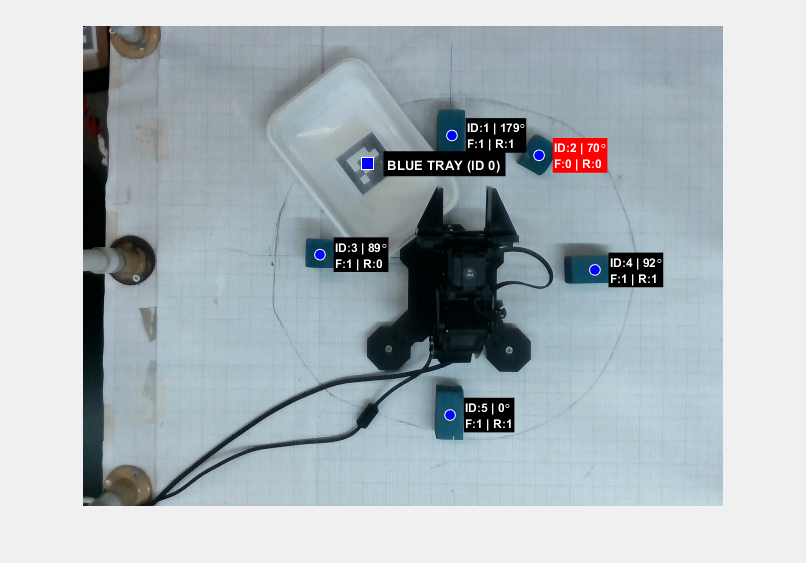

drawnow limitrate; shg; 

uiwait(f);

if isvalid(btn), delete(btn); end

disp('Button clicked! Proceeding to hardware sequence...');

Button clicked! Proceeding to hardware sequence...


drawnow; shg; 

disp('Waiting for user confirmation to proceed...');

Waiting for user confirmation to proceed...


h_msg = msgbox('Review the target map. Click OK to begin the physical sorting sequence...', 'Ready to Sort');
uiwait(h_msg); 
input('Press Enter to begin the physical sorting sequence...', 's');

%% 5. INITIALIZE ROBOT CONNECTION
%% =================================================================
port = 'COM5'; 
numServos = 5; 
arb = Arbotix('port', port, 'nservos', numServos);

i = 4

disp('Maximizing servo stiffness...');

Maximizing servo stiffness...


ADDR_CW_COMPLIANCE_MARGIN = 26;
ADDR_CCW_COMPLIANCE_MARGIN = 27;

arb.writedata1(1, ADDR_CW_COMPLIANCE_MARGIN, 2);
arb.writedata1(1, ADDR_CCW_COMPLIANCE_MARGIN,2);
arb.writedata1(2, ADDR_CW_COMPLIANCE_MARGIN, 8);
arb.writedata1(2, ADDR_CCW_COMPLIANCE_MARGIN, 8);
pause(0.5); 

jaw_open_val  = 34; jaw_close_val = 27;
speed = 100;
pick_z_offset_mm = 40;  
place_z_offset_mm = 30; 

fprintf('Opening Jaw and Homing Robot...\n');

Opening Jaw and Homing Robot...


[~, th_open] = positionJaw(jaw_open_val);
arb.setpos(5, th_open, speed);
for i = 1:4, arb.setpos(i, 0, speed); end
pause(3);

%% =================================================================
%% 6. AUTOMATED SORTING SEQUENCE (DYNAMIC STACKING)
%% =================================================================

% Separate and Reorder Targets
rect_targets = [];
square_targets = [];

for i = 1:length(all_targets)
    if all_targets(i).is_rect
        rect_targets = [rect_targets, all_targets(i)];
    else
        square_targets = [square_targets, all_targets(i)];
    end
end
all_targets = [rect_targets, square_targets];

fprintf('\nTarget execution order updated: Rectangles first, Squares second.\n');


Target execution order updated: Rectangles first, Squares second.



% --- NEW: Dynamic Placement Variables ---
% Stack heights track how much material is currently in the tray, starting at 0
blue_current_stack_height = 0; 
green_current_stack_height = 0;

% Set the base Z coordinate for the floor of the trays. 
% If you captured 'blue_place_z' in Section 2 from the ArUco, use it.
% Otherwise, default to 5mm (assuming a thin tray bottom on the table).
if exist('blue_place_z', 'var')
    blue_floor_z = blue_place_z; 
else
    blue_floor_z = 5; 
end

if exist('green_place_z', 'var')
    green_floor_z = green_place_z;
else
    green_floor_z = 5;
end

for i = 1:length(all_targets)
    t = all_targets(i);
    if ~t.feasible
        fprintf('Skipping %s Box [%d]: Angle out of tolerance.\n', t.color, t.id);
        continue; 
    end
    
    shape_str = 'Square'; if t.is_rect, shape_str = 'Rectangle'; end
    fprintf('\nExecuting Pick & Place for %s %s [%d]...\n', t.color, shape_str, t.id);
    
    pick_x = t.pos(1) * 1000;
    pick_y = t.pos(2) * 1000;
    pick_z = t.pos(3) * 1000; 
    
    % The height of the top of the block from the table IS its thickness
    cube_thickness = pick_z; 

    pick  = [pick_x, pick_y, pick_z, deg2rad(175)];  
    
    % --- NEW: Calculate Dynamic Place Z ---
    % Target Z = (Tray Floor) + (Existing Stack Height) + (Thickness of current cube)
    if strcmp(t.color, 'Blue')
        current_place_z = blue_floor_z + blue_current_stack_height + cube_thickness;
        place = [blue_place_x, blue_place_y, current_place_z, deg2rad(175)];
    else 
        current_place_z = green_floor_z + green_current_stack_height + cube_thickness;
        place = [green_place_x, green_place_y, current_place_z, deg2rad(175)];
    end

    pre_pick  = pick  + [0, 0, pick_z_offset_mm, 0];
    pre_place = place + [0, 0, place_z_offset_mm, 0];
    
    try
        % --- PICK SEQUENCE ---
        moveRobotToTarget(arb, pre_pick, speed, 2, 'approach'); 
        moveRobotToTarget(arb, pick, speed, 2, 'approach');     
        
        [~, th_close] = positionJaw(jaw_close_val);
        arb.setpos(5, th_close, speed); pause(2);
        
        moveRobotToTarget(arb, pre_pick, speed, 2, 'retract');  
        
        % GO HOME (Safe sequence)
        for j = 2:4
            arb.setpos(j, 0, speed); 
        end
        pause(1);
        arb.setpos(1, 0, speed); 
        pause(1);
        
        % --- PLACE SEQUENCE ---
        moveRobotToTarget(arb, pre_place, speed, 1, 'approach'); 
        moveRobotToTarget(arb, place, speed, 1, 'approach');     
        
        arb.setpos(5, th_open, speed); pause(1);
        
        moveRobotToTarget(arb, pre_place, speed, 1, 'retract');  
        
        % GO HOME (Safe sequence)
        for j = 2:4
            arb.setpos(j, 0, speed); 
        end
        pause(1);
        arb.setpos(1, 0, speed); 
        pause(1); 
        
        % --- NEW: Update Stack Height Dynamically ---
        % Add the thickness of the block just placed to the existing stack
        if strcmp(t.color, 'Blue')
            blue_current_stack_height = blue_current_stack_height + cube_thickness;
            fprintf('  -> Blue Stack height is now: %.1f mm\n', blue_current_stack_height);
        else
            green_current_stack_height = green_current_stack_height + cube_thickness;
            fprintf('  -> Green Stack height is now: %.1f mm\n', green_current_stack_height);
        end
        
    catch ME
        fprintf('\n--> ERROR: Sequence failed for Box [%d]: %s\n', t.id, ME.message);
        arb.setpos(5, th_open, speed);
        
        % SAFE ERROR RECOVERY (Arm UP first, then base)
        for j = 2:4
            arb.setpos(j, 0, speed); 
        end
        pause(1);
        arb.setpos(1, 0, speed); 
        pause(1);
    end
end


Executing Pick & Place for Blue Rectangle [1]...


  -> Blue Stack height is now: 28.6 mm



Executing Pick & Place for Blue Rectangle [4]...


  -> Blue Stack height is now: 72.6 mm



Executing Pick & Place for Blue Rectangle [5]...


  -> Blue Stack height is now: 120.0 mm


Skipping Blue Box [2]: Angle out of tolerance.



Executing Pick & Place for Blue Square [3]...



--> ERROR: Sequence failed for Box [3]: No realizable or collision-free IK solution found for this point.



fprintf('\nAll feasible boxes sorted. Sequence Complete!\n');


All feasible boxes sorted. Sequence Complete!


## palcing horizontal

clear; clc; close all;

%% =================================================================
%% 1. CAMERA PERCEPTION & SETUP
%% =================================================================
% Initialize pipeline and config
pipe = realsense.pipeline();
cfg = realsense.config();

% Enable streams
cfg.enable_stream(realsense.stream.depth, 640, 480, realsense.format.z16, 30);
cfg.enable_stream(realsense.stream.color, 640, 480, realsense.format.rgb8, 30);

% Initialize pointcloud object
pc = realsense.pointcloud();
align_to_color = realsense.align(realsense.stream.color);

% Start pipeline
profile = pipe.start(cfg);

disp('Warming up camera...');

Warming up camera...


for i = 1:10
    fs = pipe.wait_for_frames();
    fs = align_to_color.process(fs);
    depth_frame = fs.get_depth_frame();
    color_frame = fs.get_color_frame();
    
    pc.map_to(color_frame);
    points = pc.calculate(depth_frame);
    vtx = points.get_vertices(); % Note: Vertices are in METERS
end

% Stop streaming


% Extract RGB & HSV
color_data = color_frame.get_data();
I = permute(reshape(color_data', [3, 640, 480]), [3 2 1]);
hsvI = rgb2hsv(I);
H = hsvI(:,:,1); S = hsvI(:,:,2); V = hsvI(:,:,3);

% Transformation Matrix (Camera to World)
T_world_camera =  [-0.0105   -0.9991   -0.0408    0.0065;
                   -0.9999    0.0103    0.0047    0.0586;
                   -0.0043    0.0408   -0.9992    0.7110;
                         0         0         0    1.0000];

valid_depth = (vtx(:,3) > 0); 

%% =================================================================
%% 2. DETECT DESTINATION TRAYS (VIA ARUCO MARKERS)
%% =================================================================
disp('Detecting ArUco Markers for Destination Trays (ID 0 = Blue, ID 2 = Green)...');

Detecting ArUco Markers for Destination Trays (ID 0 = Blue, ID 2 = Green)...


[markerIds, markerLocs] = readArucoMarker(I);

blue_bin_found = false;
green_bin_found = false;

if ~isempty(markerIds)
    for i = 1:length(markerIds)
        current_id = markerIds(i);
        corners = markerLocs(:,:,i);
        
        % Create a 2D binary mask from the ArUco corners
        mask_2d = poly2mask(corners(:,1), corners(:,2), 480, 640);
        mask_1d = reshape(mask_2d', [], 1);
        
        bin_vtx = vtx(valid_depth & mask_1d, :);
        
        if ~isempty(bin_vtx)
            bin_pos_cam = mean(bin_vtx, 1);
            bin_pos_world_homog = T_world_camera * [bin_pos_cam, 1]';
            
            % Assign to respective tray based on ID
            % Assign to respective tray based on ID
            if current_id == 0
                blue_place_x = bin_pos_world_homog(1) * 1000;
                blue_place_y = bin_pos_world_homog(2) * 1000;
                blue_bin_found = true;
                
                % --- NEW: Save the mask for closed-loop verification ---
                blue_tray_mask_1d = mask_1d; 
                
                blue_pixel_x = mean(corners(:,1));
                blue_pixel_y = mean(corners(:,2));
                fprintf('Blue Tray (ID 0) Detected at World X: %.1f mm, Y: %.1f mm\n', blue_place_x, blue_place_y);
                
            elseif current_id == 2
                green_place_x = bin_pos_world_homog(1) * 1000;
                green_place_y = bin_pos_world_homog(2) * 1000;
                green_bin_found = true;
                
                % --- NEW: Save the mask for closed-loop verification ---
                green_tray_mask_1d = mask_1d;
                
                green_pixel_x = mean(corners(:,1));
                green_pixel_y = mean(corners(:,2));
                fprintf('Green Tray (ID 2) Detected at World X: %.1f mm, Y: %.1f mm\n', green_place_x, green_place_y);
            end
        end
    end
end

Blue Tray (ID 0) Detected at World X: -33.6 mm, Y: 147.7 mm


Green Tray (ID 2) Detected at World X: 86.1 mm, Y: -109.1 mm



% Fallbacks if either tray is not detected
if ~blue_bin_found
    disp('WARNING: Blue Tray (ID 0) not found. Defaulting to x=160, y=0');
    blue_place_x = 160; blue_place_y = 0;
end
if ~green_bin_found
    disp('WARNING: Green Tray (ID 2) not found. Defaulting to x=0, y=150');
    green_place_x = 0; green_place_y = 150;
end

%% =================================================================
%% 3. EXTRACT TARGETS (BLUE & GREEN BLOCKS)
%% =================================================================
% Blue Mask
hueMask_B = (H > 0.52) & (H < 0.65); 
level_B = max(graythresh(S), 0.40); 
mask_blue = bwareaopen(imfill(hueMask_B & (S > level_B) & (V > 0.25), 'holes'), 100);

% Green Mask
H_MIN_GREEN = 0.232; H_MAX_GREEN = 0.490;
S_MIN_GREEN = 0.292; S_MAX_GREEN = 1.000;
V_MIN_GREEN = 0.138; V_MAX_GREEN = 0.579;
mask_green = bwareaopen(imfill((H >= H_MIN_GREEN) & (H <= H_MAX_GREEN) & ...
            (S >= S_MIN_GREEN) & (S <= S_MAX_GREEN) & ...
            (V >= V_MIN_GREEN) & (V <= V_MAX_GREEN), 'holes'), 100);

jaw_tolerance_deg = 12;

% Create 2D Pixel maps to track cluster centroids on the image
[U, V] = meshgrid(1:640, 1:480); % U is X (columns), V is Y (rows)
U_1d = reshape(U', [], 1);
V_1d = reshape(V', [], 1);

% Helper function to process point clouds into target arrays


% Call the function for both colors
blue_targets = get_targets(mask_blue, vtx, valid_depth, T_world_camera, jaw_tolerance_deg, 'Blue', U_1d, V_1d);
green_targets = get_targets(mask_green, vtx, valid_depth, T_world_camera, jaw_tolerance_deg, 'Green', U_1d, V_1d);

% To maintain sequential IDs overall:
all_targets = [];
current_id = 1;
for i = 1:length(blue_targets)
    blue_targets(i).id = current_id; current_id = current_id + 1;
end
for i = 1:length(green_targets)
    green_targets(i).id = current_id; current_id = current_id + 1;
end
all_targets = [blue_targets, green_targets];

%% =================================================================
%% 4. DEBUGGING / VERIFICATION TABLE & VISUALIZATION
%% =================================================================
fprintf('\n===========================================================================\n');

fprintf(' DETECTED OBJECTS REPORT \n');

 DETECTED OBJECTS REPORT 


fprintf('===========================================================================\n');

fprintf('%-5s | %-7s | %-6s | %-6s | %-6s | %-7s | %-6s | %-10s\n', ...
    'ID', 'Color', 'X(mm)', 'Y(mm)', 'Z(mm)', 'Angle', 'IsRect', 'Feasible');

ID    | Color   | X(mm)  | Y(mm)  | Z(mm)  | Angle   | IsRect | Feasible  


fprintf('---------------------------------------------------------------------------\n');

---------------------------------------------------------------------------



for i = 1:length(all_targets)
    t = all_targets(i);
    feasible_str = 'YES'; if ~t.feasible, feasible_str = 'NO'; end
    rect_str = 'NO'; if t.is_rect, rect_str = 'YES'; end
    fprintf('%-5d | %-7s | %-6.1f | %-6.1f | %-6.1f | %-7.1f | %-6s | %-10s\n', ...
        t.id, t.color, t.pos(1)*1000, t.pos(2)*1000, t.pos(3)*1000, t.angle, rect_str, feasible_str);
end

1     | Blue    | 111.7  | 106.0  | 51.9   | 45.0    | NO     | YES       
2     | Blue    | -26.4  | -144.0 | 39.1   | 89.0    | YES    | YES       
3     | Green   | 129.8  | -1.2   | 53.3   | 89.0    | NO     | YES       
4     | Green   | -161.8 | -2.6   | 44.4   | 172.0   | YES    | YES       


fprintf('===========================================================================\n\n');


% Create the figure window explicitly
f = figure('Name', 'Workspace Target Debug', 'NumberTitle', 'off', 'Position', [100, 100, 800, 600]);
imshow(I); 
hold on;

% --- NEW: Draw Both ArUco Trays ---
if blue_bin_found
    plot(blue_pixel_x, blue_pixel_y, 's', 'MarkerSize', 12, 'MarkerEdgeColor', 'w', 'MarkerFaceColor', 'b');
    text(blue_pixel_x + 20, blue_pixel_y, 'BLUE TRAY (ID 0)', 'Color', 'w', 'BackgroundColor', 'k', 'FontWeight', 'bold', 'FontSize', 10);
end

if green_bin_found
    plot(green_pixel_x, green_pixel_y, 's', 'MarkerSize', 12, 'MarkerEdgeColor', 'w', 'MarkerFaceColor', 'g');
    text(green_pixel_x + 20, green_pixel_y, 'GREEN TRAY (ID 2)', 'Color', 'w', 'BackgroundColor', 'k', 'FontWeight', 'bold', 'FontSize', 10);
end

for i = 1:length(all_targets)
    t = all_targets(i);
    marker_color = 'b'; if strcmp(t.color, 'Green'), marker_color = 'g'; end
    text_bg = 'k'; if ~t.feasible, text_bg = 'r'; end
    
    plot(t.pixel_x, t.pixel_y, 'o', 'MarkerSize', 8, 'MarkerEdgeColor', 'w', 'MarkerFaceColor', marker_color);
    annot_str = sprintf('ID:%d | %d\\circ\nF:%d | R:%d', t.id, round(t.angle), t.feasible, t.is_rect);
    text(t.pixel_x + 15, t.pixel_y, annot_str, 'Color', 'w', 'BackgroundColor', text_bg, 'FontSize', 9, 'FontWeight', 'bold', 'Margin', 1);
end
hold off;

% UI Button
btn = uicontrol(f, 'Style', 'pushbutton', 'String', 'START ROBOT', 'Position', [20, 20, 150, 50], ...
    'FontSize', 12, 'FontWeight', 'bold', 'BackgroundColor', 'g', 'Callback', 'uiresume(gcbf)');

disp('Image generated. Waiting for you to click "START ROBOT" on the image window...');

Image generated. Waiting for you to click "START ROBOT" on the image window...


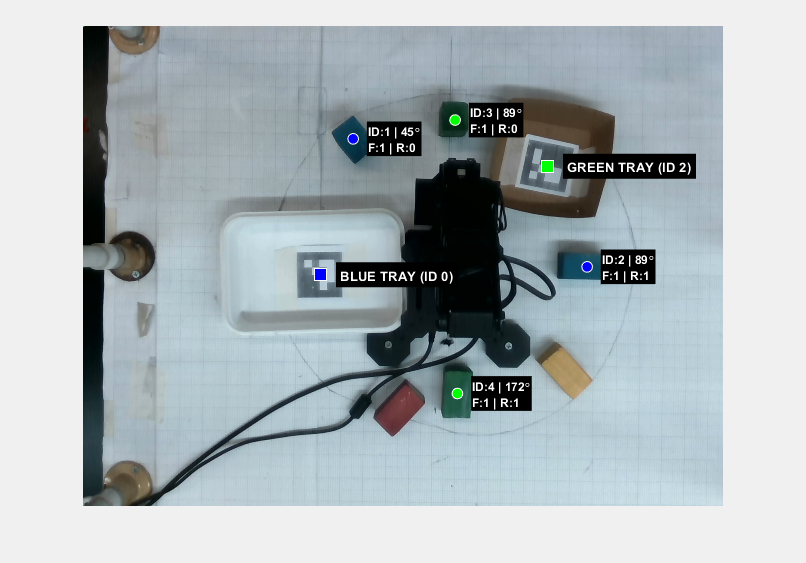

drawnow limitrate; shg; 

uiwait(f);

if isvalid(btn), delete(btn); end

disp('Button clicked! Proceeding to hardware sequence...');

Button clicked! Proceeding to hardware sequence...


drawnow; shg; 

disp('Waiting for user confirmation to proceed...');

Waiting for user confirmation to proceed...


h_msg = msgbox('Review the target map. Click OK to begin the physical sorting sequence...', 'Ready to Sort');
uiwait(h_msg); 
input('Press Enter to begin the physical sorting sequence...', 's');

%% 5. INITIALIZE ROBOT CONNECTION
%% =================================================================
port = 'COM5'; 
numServos = 5; 
arb = Arbotix('port', port, 'nservos', numServos);

serPort COM5is in use.   Closing it.


i = 4

disp('Maximizing servo stiffness...');

Maximizing servo stiffness...


ADDR_CW_COMPLIANCE_MARGIN = 26;
ADDR_CCW_COMPLIANCE_MARGIN = 27;

arb.writedata1(1, ADDR_CW_COMPLIANCE_MARGIN, 2);
arb.writedata1(1, ADDR_CCW_COMPLIANCE_MARGIN,2);
arb.writedata1(2, ADDR_CW_COMPLIANCE_MARGIN, 8);
arb.writedata1(2, ADDR_CCW_COMPLIANCE_MARGIN, 8);
pause(0.5); 

jaw_open_val  = 34; jaw_close_val = 27;
speed = 100;
pick_z_offset_mm = 40;  
place_z_offset_mm = 30; 

fprintf('Opening Jaw and Homing Robot...\n');

Opening Jaw and Homing Robot...


[~, th_open] = positionJaw(jaw_open_val);
arb.setpos(5, th_open, speed);
for i = 1:4, arb.setpos(i, 0, speed); end
pause(3);

%% =================================================================
%% 6. AUTOMATED SORTING SEQUENCE (DYNAMIC STACKING)
%% =================================================================

% Separate and Reorder Targets
rect_targets = [];
square_targets = [];

for i = 1:length(all_targets)
    if all_targets(i).is_rect
        rect_targets = [rect_targets, all_targets(i)];
    else
        square_targets = [square_targets, all_targets(i)];
    end
end
all_targets = [rect_targets, square_targets];

fprintf('\nTarget execution order updated: Rectangles first, Squares second.\n');


Target execution order updated: Rectangles first, Squares second.



% --- NEW: Dynamic Placement Variables ---
% Stack heights track how much material is currently in the tray, starting at 0
blue_current_stack_height = 0; 
green_current_stack_height = 0;

% Set the base Z coordinate for the floor of the trays. 
% If you captured 'blue_place_z' in Section 2 from the ArUco, use it.
% Otherwise, default to 5mm (assuming a thin tray bottom on the table).
if exist('blue_place_z', 'var')
    blue_floor_z = blue_place_z; 
else
    blue_floor_z = 5; 
end

if exist('green_place_z', 'var')
    green_floor_z = green_place_z;
else
    green_floor_z = 5;
end

for i = 1:length(all_targets)
    t = all_targets(i);
    if ~t.feasible
        fprintf('Skipping %s Box [%d]: Angle out of tolerance.\n', t.color, t.id);
        continue; 
    end
    
    shape_str = 'Square'; if t.is_rect, shape_str = 'Rectangle'; end
    fprintf('\nExecuting Pick & Place for %s %s [%d]...\n', t.color, shape_str, t.id);
    
    pick_x = t.pos(1) * 1000;
    pick_y = t.pos(2) * 1000;
    pick_z = t.pos(3) * 1000; 
    
    % The height of the top of the block from the table IS its thickness
    cube_thickness = pick_z; 
    pick  = [pick_x, pick_y, pick_z, deg2rad(175)];  
    
    % --- NEW: REAL-TIME DEPTH VERIFICATION ---
    % Because the robot is currently in its HOME position (out of the camera's way), 
    % this is the perfect time to take a fresh 3D scan of the tray.
    if strcmp(t.color, 'Blue')
        % Scan the blue tray area
        actual_peak_z = scan_current_tray_height(pipe, align_to_color, pc, blue_tray_mask_1d, T_world_camera, blue_floor_z);
        
        fprintf('  -> Camera reads Blue Stack top at: %.1f mm\n', actual_peak_z);
        current_place_z = actual_peak_z + cube_thickness;
        place = [blue_place_x, blue_place_y, current_place_z, deg2rad(175)];
        
    else % Green
        % Scan the green tray area
        actual_peak_z = scan_current_tray_height(pipe, align_to_color, pc, green_tray_mask_1d, T_world_camera, green_floor_z);
        
        fprintf('  -> Camera reads Green Stack top at: %.1f mm\n', actual_peak_z);
        current_place_z = actual_peak_z + cube_thickness;
        place = [green_place_x, green_place_y, current_place_z, deg2rad(175)];
    end

    pre_pick  = pick  + [0, 0, pick_z_offset_mm, 0];
    pre_place = place + [0, 0, place_z_offset_mm, 0];
    
    try
        % --- PICK SEQUENCE ---
        moveRobotToTarget(arb, pre_pick, speed, 2, 'approach'); 
        moveRobotToTarget(arb, pick, speed, 2, 'approach');     
        
        [~, th_close] = positionJaw(jaw_close_val);
        arb.setpos(5, th_close, speed); pause(2);
        
        moveRobotToTarget(arb, pre_pick, speed, 2, 'retract');  
        
        % GO HOME (Safe sequence)
        for j = 2:4
            arb.setpos(j, 0, speed); 
        end
        pause(1);
        arb.setpos(1, 0, speed); 
        pause(1);
        
        % --- PLACE SEQUENCE ---
        moveRobotToTarget(arb, pre_place, speed, 1, 'approach'); 
        moveRobotToTarget(arb, place, speed, 1, 'approach');     
        
        arb.setpos(5, th_open, speed); pause(1);
        
        moveRobotToTarget(arb, pre_place, speed, 1, 'retract');  
        
        % GO HOME (Safe sequence)
        for j = 2:4
            arb.setpos(j, 0, speed); 
        end
        pause(1);
        arb.setpos(1, 0, speed); 
        pause(1); 
        
        % --- NEW: Update Stack Height Dynamically ---
        % Add the thickness of the block just placed to the existing stack
        if strcmp(t.color, 'Blue')
            blue_current_stack_height = blue_current_stack_height + cube_thickness;
            fprintf('  -> Blue Stack height is now: %.1f mm\n', blue_current_stack_height);
        else
            green_current_stack_height = green_current_stack_height + cube_thickness;
            fprintf('  -> Green Stack height is now: %.1f mm\n', green_current_stack_height);
        end
        
    catch ME
        fprintf('\n--> ERROR: Sequence failed for Box [%d]: %s\n', t.id, ME.message);
        arb.setpos(5, th_open, speed);
        
        % SAFE ERROR RECOVERY (Arm UP first, then base)
        for j = 2:4
            arb.setpos(j, 0, speed); 
        end
        pause(1);
        arb.setpos(1, 0, speed); 
        pause(1);
    end
end


Executing Pick & Place for Blue Rectangle [2]...


  -> Camera reads Blue Stack top at: 18.7 mm


  -> Blue Stack height is now: 39.1 mm



Executing Pick & Place for Green Rectangle [4]...


  -> Camera reads Green Stack top at: 449.6 mm



--> ERROR: Sequence failed for Box [4]: No realizable or collision-free IK solution found for this point.



Executing Pick & Place for Blue Square [1]...


  -> Camera reads Blue Stack top at: 45.6 mm


  -> Blue Stack height is now: 91.0 mm



Executing Pick & Place for Green Square [3]...


  -> Camera reads Green Stack top at: 11.6 mm


  -> Green Stack height is now: 53.3 mm



fprintf('\nAll feasible boxes sorted. Sequence Complete!\n');


All feasible boxes sorted. Sequence Complete!


pipe.stop();
disp('Camera stopped. Processing final frame for Scene Analysis...');

Camera stopped. Processing final frame for Scene Analysis...




function max_z_mm = scan_current_tray_height(pipe, align_to_color, pc, mask_1d, T_world_camera, default_floor_z)
    % 1. Flush the buffer to ensure we get a fresh, real-time frame
    for k = 1:5
        fs = pipe.wait_for_frames();
    end
    fs = align_to_color.process(fs);
    depth_frame = fs.get_depth_frame();
    color_frame = fs.get_color_frame();

    % 2. Generate updated point cloud
    pc.map_to(color_frame);
    points = pc.calculate(depth_frame);
    vtx = points.get_vertices(); 
    valid_depth = (vtx(:,3) > 0);

    % 3. Apply our saved 2D tray mask to the new 3D data
    valid_mask = valid_depth & mask_1d;
    tray_vtx = vtx(valid_mask, :);

    if isempty(tray_vtx)
        max_z_mm = default_floor_z; % Fallback if camera loses depth
    else
        % 4. Transform to world coordinates and find the absolute highest point
        points_cam_homog = [tray_vtx, ones(size(tray_vtx, 1), 1)]';
        points_world = (T_world_camera * points_cam_homog)';
        max_z_mm = max(points_world(:, 3)) * 1000; % Convert back to mm
    end
end